load CrackData.mat
crackData

crackData = 200×4 table
    NumRegions    Area    MaxWidth     fileName  
    __________    ____    ________    ___________

        2         2461     17.889     "00001.jpg"
        2         2125     17.889     "00002.jpg"
        2         2417         16     "00003.jpg"
        1         2438     14.142     "00004.jpg"
        4         1479     18.439     "00005.jpg"
        1         2356         14     "00006.jpg"
        1         2926     18.974     "00007.jpg"
        1         2573     15.232     "00008.jpg"
        2         1861     14.142     "00009.jpg"
        2         2663     17.088     "00010.jpg"
        1         3149     23.409     "00011.jpg"
        1         2722     18.974     "00012.jpg"
        2         1221      14.56     "00013.jpg"
        1         3050      25.06     "00014.jpg"
        1         2346         14     "

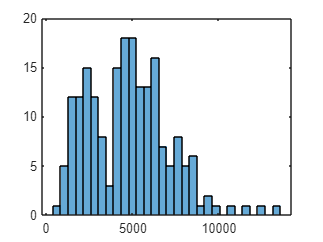

histogram(crackData.Area, 30)

cutoffArea = 4000;
crackData.Risk = discretize(crackData.Area, [0, cutoffArea, inf], ...
    "categorical", ["Mild", "Severe"]);

dsSevere = imageDatastore(crackData.fileName(crackData.Risk == "Severe"));

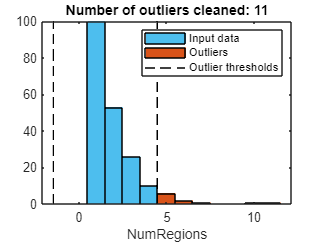

% Remove outliers
[newTable,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(crackData,...
    "ThresholdFactor",4,"DataVariables","NumRegions");

% Display results
figure
[~,binEdges] = histcounts(crackData.NumRegions);
binEdges = unique([binEdges thresholdLow.NumRegions thresholdHigh.NumRegions]);
binEdges = binEdges(isfinite(binEdges));
histogram(crackData.NumRegions,"BinEdges",binEdges,...
    "FaceColor",[77 190 238]/255,"FaceAlpha",1,"DisplayName","Input data")
hold on

% Plot outliers
histogram(crackData.NumRegions(outlierIndices),"BinEdges",binEdges,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","Outliers")

% Plot outlier thresholds
plot([thresholdLow.NumRegions*[1 1] NaN thresholdHigh.NumRegions*[1 1]],...
    [ylim missing ylim],"k--","DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
xlabel("NumRegions")

clear thresholdLow thresholdHigh binEdges

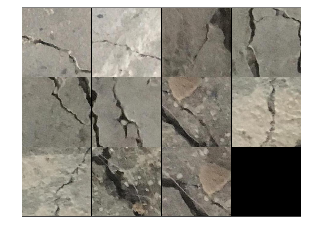

outlierImages = crackData.fileName(outlierIndices);
montage(outlierImages, "BorderSize", 1)

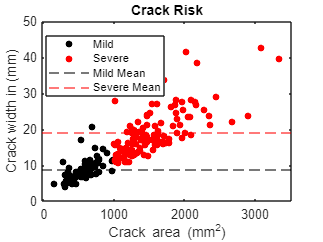

% Fill in your code here
crackData.MaxWidth = crackData.MaxWidth * 0.5;
crackData.Area = crackData.Area / 4;
mildImages = crackData.MaxWidth(crackData.Risk == "Mild");
severeImages = crackData.MaxWidth(crackData.Risk == "Severe");
mildMeanWidth =  mean(mildImages(:));
severeMeanWidth = mean(severeImages(:));
severeMedianWidth = median(severeImages(:));


%%%%% Uncomment the code below to plot your results
gscatter(crackData.Area,crackData.MaxWidth,crackData.Risk,"kr")
yline(mildMeanWidth,"k--","DisplayName","Mild Mean")
yline(severeMeanWidth,"r--","DisplayName","Severe Mean")
title("Crack Risk")
xlabel("Crack area (mm^2)")
ylabel("Crack width in (mm)")

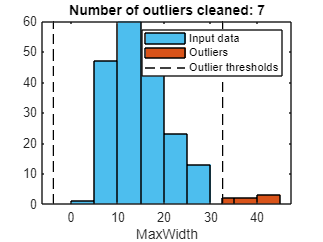

% Remove outliers
[newTable2,outlierIndicesWithMaxWidth,~,thresholdLow2,thresholdHigh2] = rmoutliers(crackData,...
    "DataVariables","MaxWidth");

% Display results
figure
[~,binEdges2] = histcounts(crackData.MaxWidth);
binEdges2 = unique([binEdges2 thresholdLow2.MaxWidth thresholdHigh2.MaxWidth]);
binEdges2 = binEdges2(isfinite(binEdges2));
histogram(crackData.MaxWidth,"BinEdges",binEdges2,"FaceColor",[77 190 238]/255,...
    "FaceAlpha",1,"DisplayName","Input data")
hold on

% Plot outliers
histogram(crackData.MaxWidth(outlierIndicesWithMaxWidth),"BinEdges",binEdges2,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","Outliers")

% Plot outlier thresholds
plot([thresholdLow2.MaxWidth*[1 1] NaN thresholdHigh2.MaxWidth*[1 1]],...
    [ylim missing ylim],"k--","DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndicesWithMaxWidth))
legend
xlabel("MaxWidth")

clear thresholdLow2 thresholdHigh2 binEdges2